% (y+exp(x)*sin(y))*dx+(x+exp(x)*cos(y))*dy=0

clear
% 1)
% y'=-(y+exp(x)*sin(y))/(x+exp(x)*cos(y))
syms x y(x) C
eqn=diff(y(x))==-(y+exp(x)*sin(y))/(x+exp(x)*cos(y))

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=-\frac{y\left(x\right)+\sin\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}}{x+\cos\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}}$$

ySol=dsolve(eqn)

$$ySol = \mathrm{solve}\left(C_{29}+{\mathrm{e}}^{x}\,\sin\left(y\right)+x\,y,y\right)$$

% solve(exp(x)*sin(y) + x*y == -C4, y)
eq1=exp(x)*sin(y) + x*y == C

$$eq1(x) = \sin\left(y\left(x\right)\right)\,{\mathrm{e}}^{x}+x\,y\left(x\right)=C$$


% 2)
syms x y dx dy C
eq1=(y+exp(x)*sin(y))*dx+(x+exp(x)*cos(y))*dy

$$eq1 = \mathrm{dy}\,\left(x+{\mathrm{e}}^{x}\,\cos\left(y\right)\right)+\mathrm{dx}\,\left(y+{\mathrm{e}}^{x}\,\sin\left(y\right)\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} y+{\mathrm{e}}^{x}\,\sin\left(y\right) & x+{\mathrm{e}}^{x}\,\cos\left(y\right) \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = y+{\mathrm{e}}^{x}\,\sin\left(y\right)$$

$$Q = x+{\mathrm{e}}^{x}\,\cos\left(y\right)$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 0$$

% dPy==dQx

% U(x,y)
% dUx=P, dUy=Q
syms C(y)
U=int(P,x)+C(y)

$$U = C\left(y\right)+{\mathrm{e}}^{x}\,\sin\left(y\right)+x\,y$$

% C(y) + exp(x)*sin(y) + x*y
simplify(diff(U,y)-Q)

$$ans = \frac{\partial }{\partial y}C\left(y\right)$$

% diff(C(y), y) = 0
% C(y)=C1
% exp(x)*sin(y) + x*y == -C1
U=exp(x)*sin(y) + x*y

$$U = {\mathrm{e}}^{x}\,\sin\left(y\right)+x\,y$$

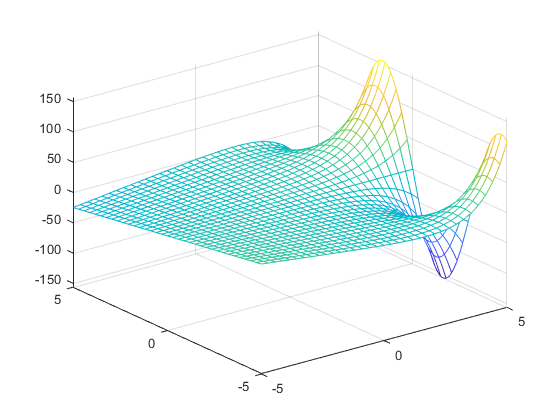

fmesh(U)


% 3)
x0=0; y0=0;
U=simplify(int(P,x,x0,x)+int(subs(Q,x,x0),y,y0,y))

$$U = {\mathrm{e}}^{x}\,\sin\left(y\right)+x\,y$$

syms C
eq2=U==C

$$eq2 = {\mathrm{e}}^{x}\,\sin\left(y\right)+x\,y=C$$